# [Solution] Expectation values in the AKLT state

Author: [Seung-Sup Lee](https://cqm.snu.ac.kr)

## Solution to Exercise (a): Magnetization

First, we create the tensor at each bulk site of the AKLT state.

clear

AKLT = zeros(2,2,3);
% local spin S_z = +1
AKLT(1,2,1) = sqrt(2/3);
% local spin S_z = 0
AKLT(1,1,2) = -1/sqrt(3);
AKLT(2,2,2) = +1/sqrt(3);
% local spin S_z = -1
AKLT(2,1,3) = -sqrt(2/3);

Defain the array `Sz_val` to which the magnetization values will be assigned. Its first dimension runs over site indices. Its second and third indices are for the boundary conditions $\alpha$ for the leftmost leg and $\beta$ for the rightmost leg, respectively.

L = 50; % number of sites
[S,I] = getLocalSpace('Spin',1);
Sz = S(:,:,2); % spin-z
Sz_val = zeros(L,2,2);

Now we compute the magnetization.

for it1 = (1:2) % boundary condition \alpha
    for it2 = (1:2) % boundary condition \beta
        % the whole MPS
        M = cell(1,L);
        M(:) = {AKLT};
        M{1} = M{1}(it1,:,:);
        M{end} = M{end}(:,it2,:);
        M = canonForm(M,L,[],0); % left-canonical form
        
        for itN = (1:L) % compute magnetization at itN
            T = updateLeft([],[],M{itN},Sz,2,M{itN});

            for itN2 = (itN+1:L)
                T = updateLeft(T,2,M{itN2},[],[],M{itN2});
            end
            
            Sz_val(itN,it1,it2) = T;
        end
    end
end

Compare the numerical results and the exact results.

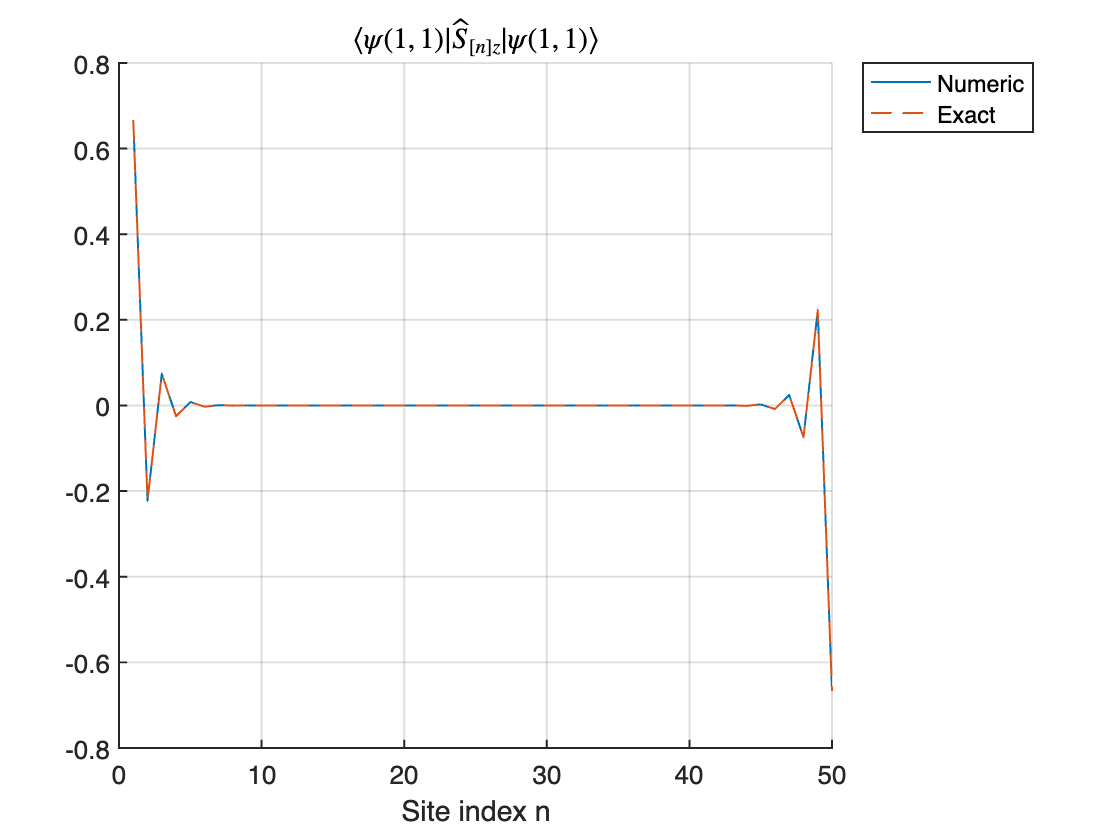

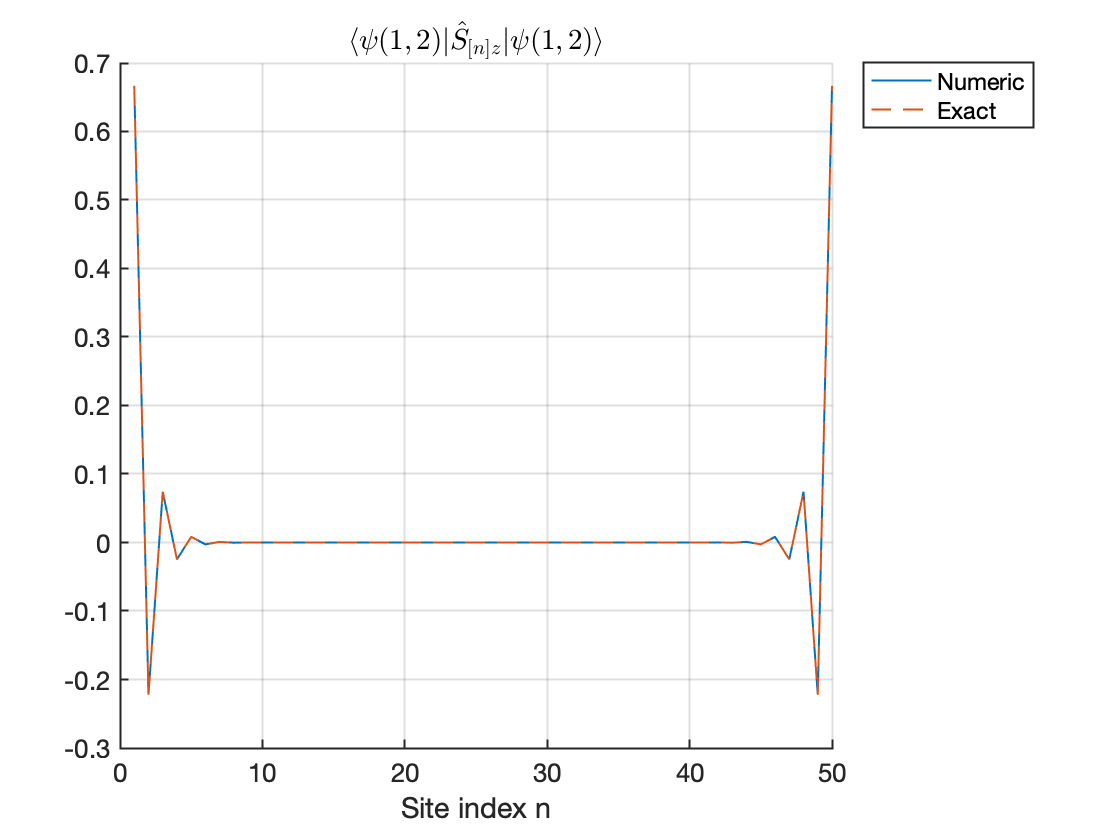

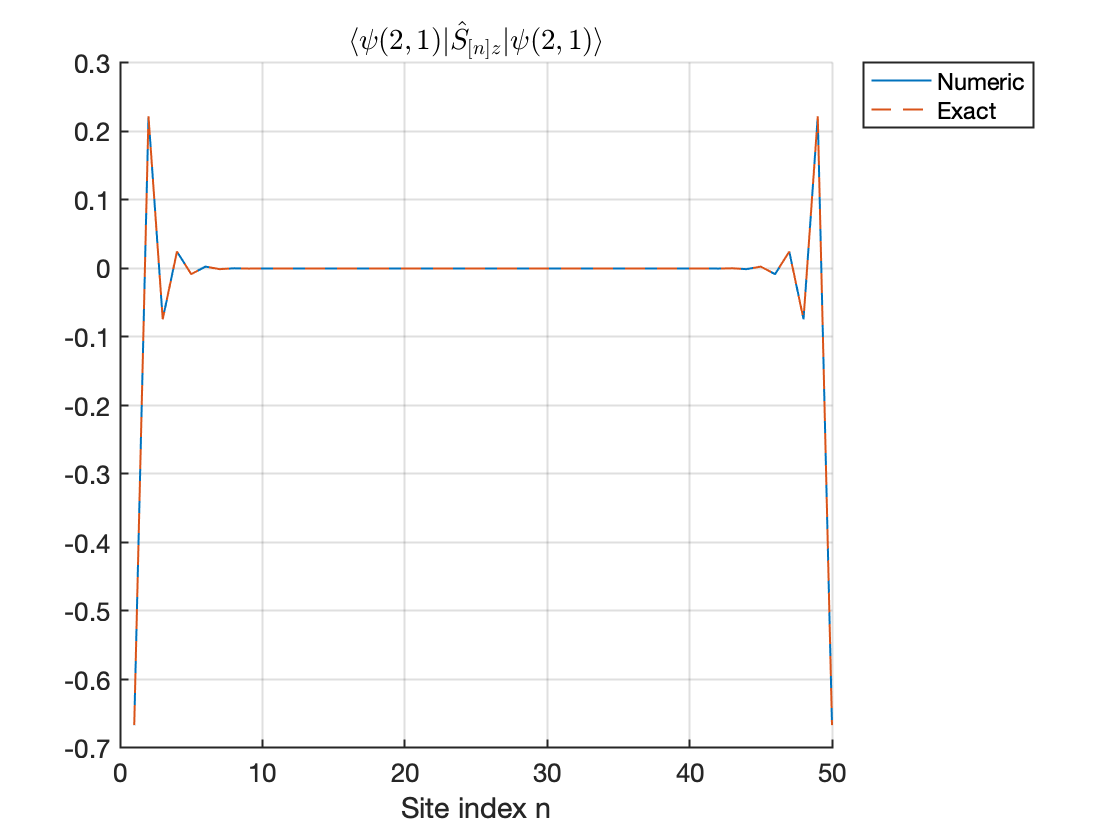

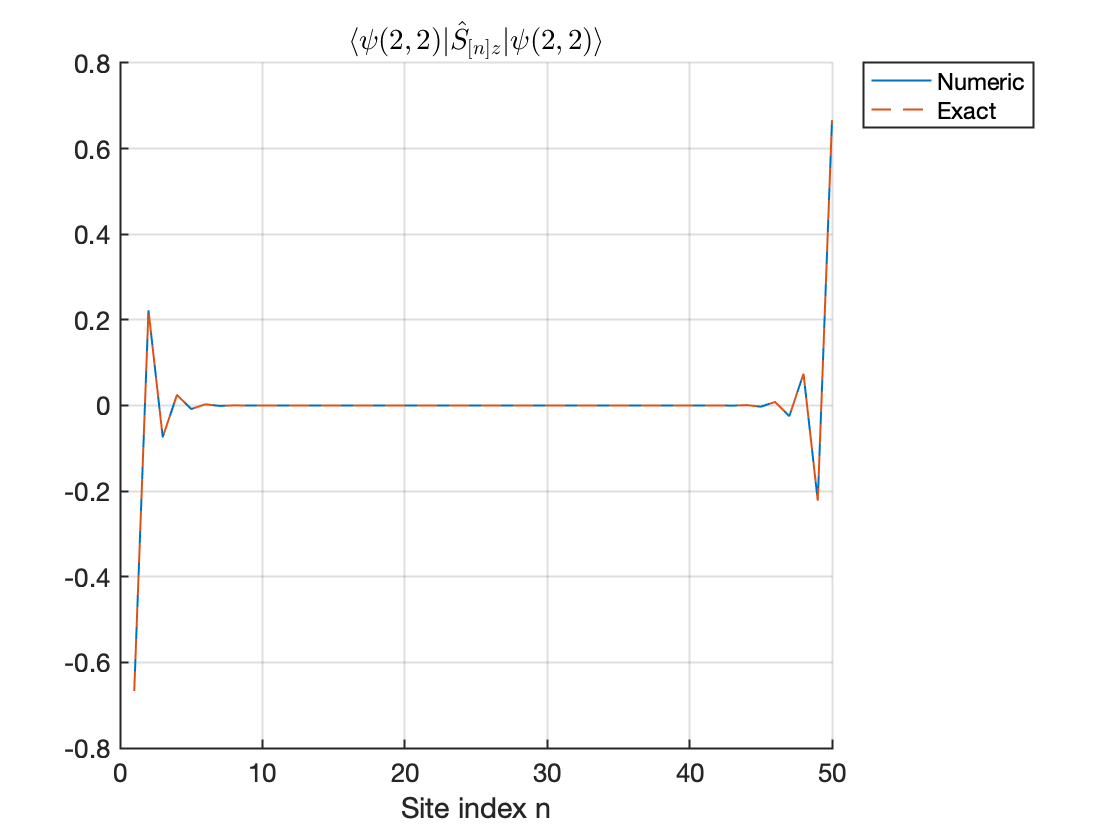

for it1 = (1:2)
    for it2 = (1:2)
        Sz_exact = (2*(-1)^it1)* ...
            ((-1/3).^(1:L).' - (-1)^(it1+it2)*(-1/3).^(L:-1:1).')./ ...
            (1 + (-1)^(it1+it2)*(-1/3)^L);

        figure;
        hold on;
        plot((1:L),Sz_val(:,it1,it2), ...
            'LineWidth',1,'LineStyle','-');
        plot((1:L),Sz_exact, ...
            'LineWidth',1,'LineStyle','--');
        hold off;
        set(gca,'LineWidth',1,'FontSize',13);
        xlabel('Site index n');
        title(['$\langle \psi(',sprintf('%i,%i',it1,it2), ...
            ')|\hat{S}_{[n]z} | \psi(',sprintf('%i,%i',it1,it2), ...
            ') \rangle$'], ...
            'Interpreter','latex');
        legend({'Numeric','Exact'},'Location','northeastoutside');
        grid on;
    end
end

Here we see that the magnetization at site 1 is positive (negative) if $\alpha = 1 (2)$, and similarly for the magnetization at site $L$. It is because $\alpha = \beta = 1$ indicates $S_z = 1/2$ in the bond space and $\alpha = \beta = 2$ indicates $S_z = -1/2$.

## Solution to Exercise (b): Spin-spin correlation

Compute the spin-spin correlation. The only difference from the above case is that another spin-z operator is contracted with the physical (local space) legs of the bra and ket tensors at the next site.

SzSz_val = zeros(L-1,2,2);
% 1st dimension: site indices within (1:(L-1))
% 2nd dimension: boundary condition for the leftmost leg
% 3rd dimension: boundary condition for the rightmost leg

for it1 = (1:2) % boundary condition \alpha
    for it2 = (1:2) % boundary condition \beta
        % the whole MPS
        M = cell(1,L);
        M(:) = {AKLT};
        M{1} = M{1}(it1,:,:);
        M{end} = M{end}(:,it2,:);
        M = canonForm(M,L,[],0); % left-canonical form
        
        for itN = (1:L-1) % compute magnetization at itN
            T = updateLeft([],[],M{itN},Sz,2,M{itN});

            % only difference!
            T = updateLeft(T,2,M{itN+1},Sz,2,M{itN+1});

            for itN2 = (itN+2:L)
                T = updateLeft(T,2,M{itN2},[],[],M{itN2});
            end
            
            SzSz_val(itN,it1,it2) = T;
        end
    end
end

Compare the numerical results and the exact results. Note that the exact result does not depend on the site index $n$.

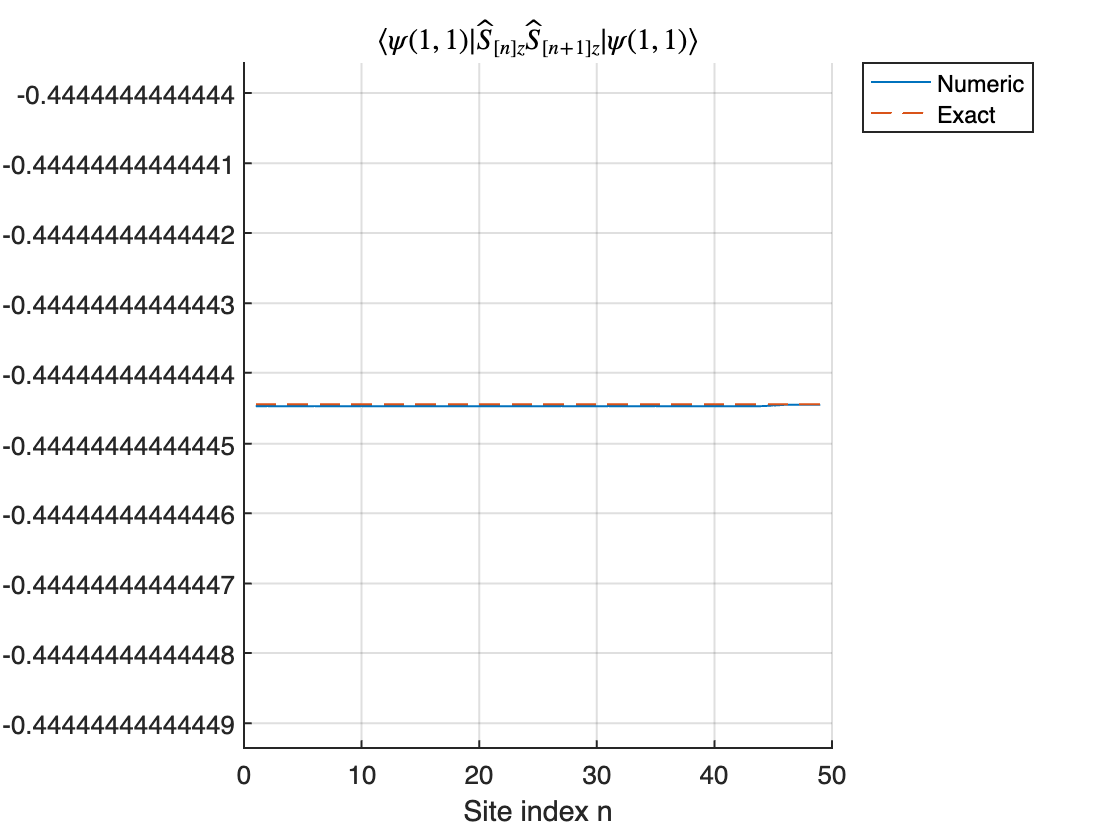

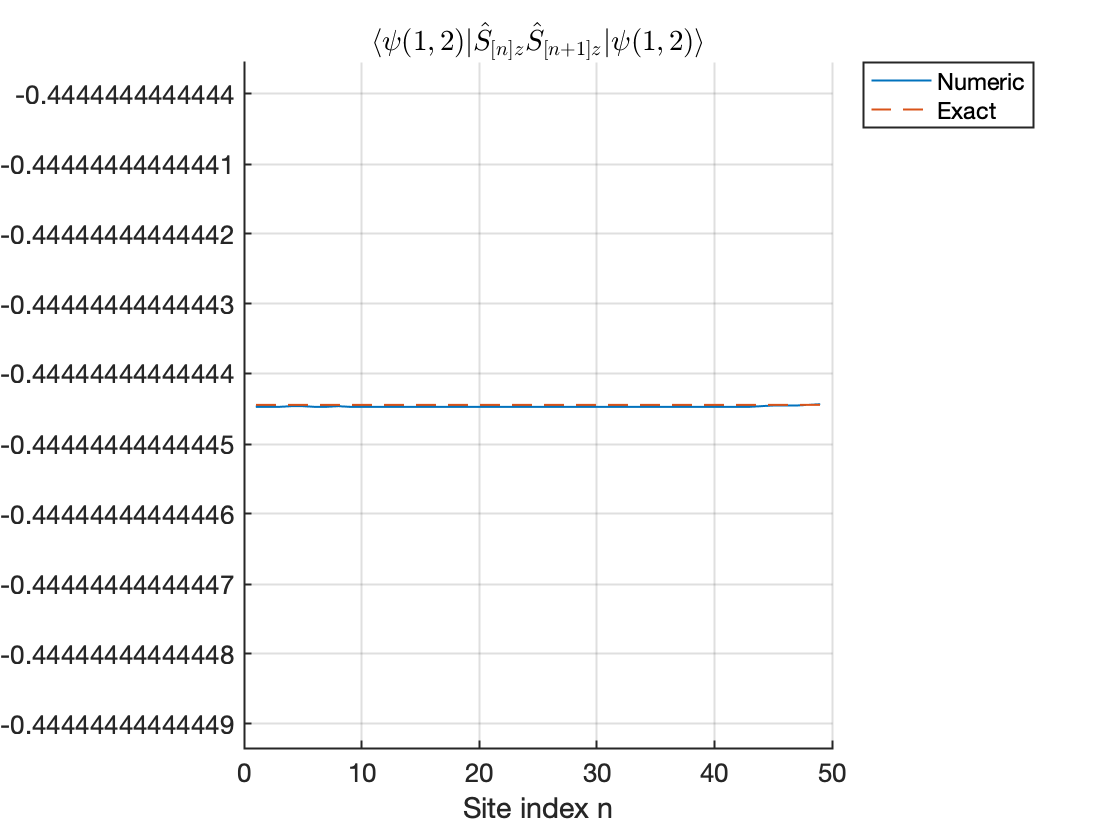

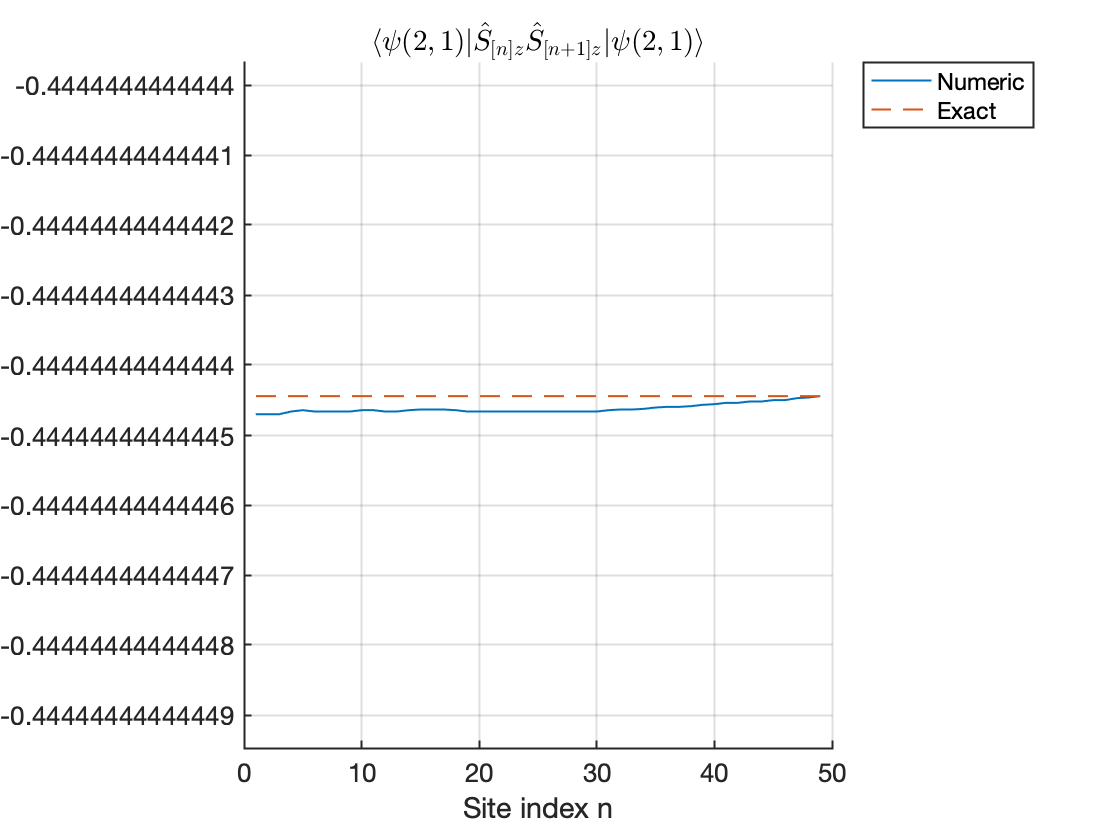

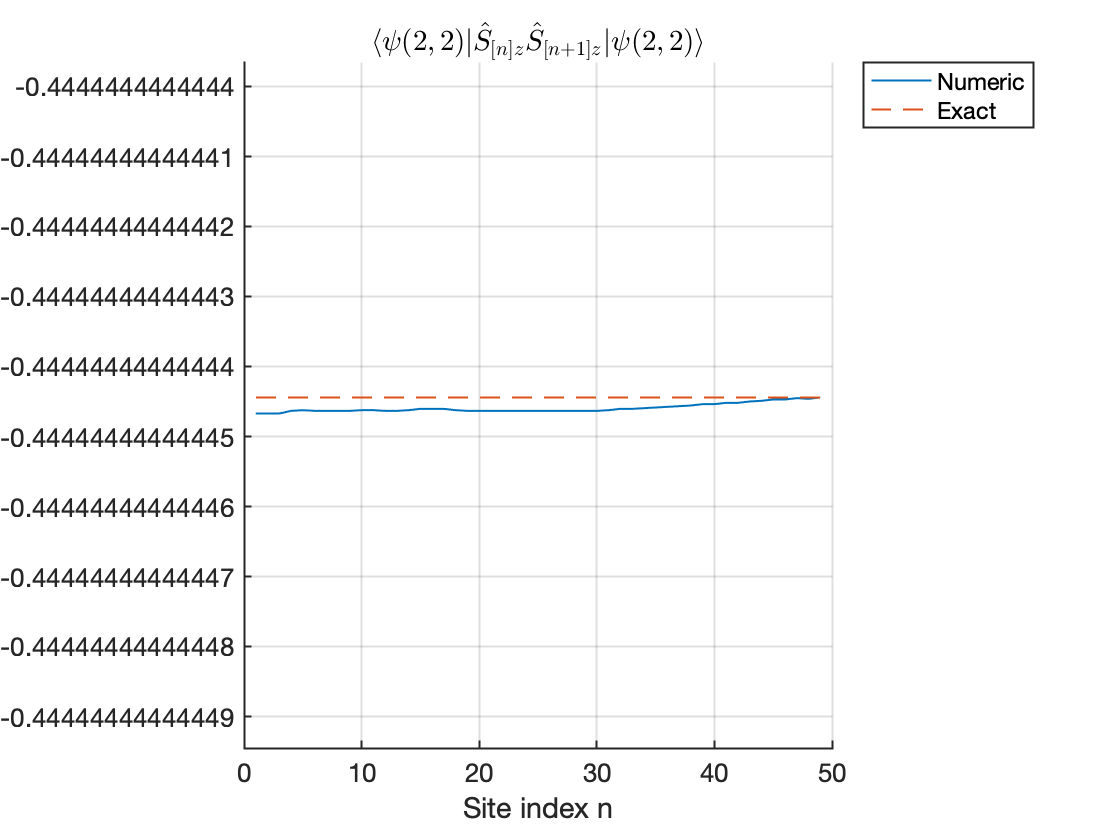

for it1 = (1:2)
    for it2 = (1:2)
        SzSz_exact = zeros(L-1,1) + ...
            ((-4/9) - 4*(-1)^(it1+it2)*(-1/3)^L)/ ...
            (1 + (-1)^(it1+it2)*(-1/3)^L);

        figure;
        hold on;
        plot((1:L-1),SzSz_val(:,it1,it2), ...
            'LineWidth',1,'LineStyle','-');
        plot((1:L-1),SzSz_exact, ...
            'LineWidth',1,'LineStyle','--');
        hold off;
        set(gca,'LineWidth',1,'FontSize',13);
        xlabel('Site index n');
        title(['$\langle \psi(',sprintf('%i,%i',it1,it2), ...
            ')|\hat{S}_{[n]z} \hat{S}_{[n+1]z}| \psi(', ...
            sprintf('%i,%i',it1,it2), ...
            ') \rangle$'], ...
            'Interpreter','latex');
        legend({'Numeric','Exact'},'Location','northeastoutside');
        grid on;
    end
end